# ドライブサイクルの確認

Copyright 2021 Michio Inoue

データセットに含まれるドライブサイクルは data_explanation.xlsx に以下の記載があります。

- Urban Dynamometer Driving Schedule (UDDS)

- Highway Fuel Economy Driving Schedule (HWFET)

- Los Angeles 92 (LA92)

- Supplemental Federal Test Procedure Driving Schedule (US06)

Cycle, Cycle_2, Cycle_3, Cycle_4, NN は上記のサイクルをランダムで組み合わせたもので、学習データ・テストデータに含まれるドライブサイクルを確認すると以下の通り。

学習データ

- Cycle

- NN

- US06

テストデータ

- UDDS

- HWFET

- LA92

- Cycle2

- Cycle3

- Cycle4

## ドライブサイクルの確認

ここでは以下のページで公開されている情報で各ドライブサイクル（US06, HWFET, UDDS, LA92）の確認をします。

[https://www.epa.gov/vehicle-and-fuel-emissions-testing/dynamometer-drive-schedules](https://www.epa.gov/vehicle-and-fuel-emissions-testing/dynamometer-drive-schedules)

以下ページからの引用

- The US06 is a high acceleration aggressive driving schedule that is often identified as the "Supplemental FTP" driving schedule.

- The EPA Urban Dynamometer Driving Schedule (UDDS) is commonly called the "LA4" or "the city test" and represents city driving conditions. It is used for light duty vehicle testing.

- The LA92 has a higher top speed, a higher average speed, less idle time, fewer stops per mile, and a higher maximum rate of acceleration.

- The Highway Fuel Economy Driving Schedule (HWFET) represents highway driving conditions under 60 mph.

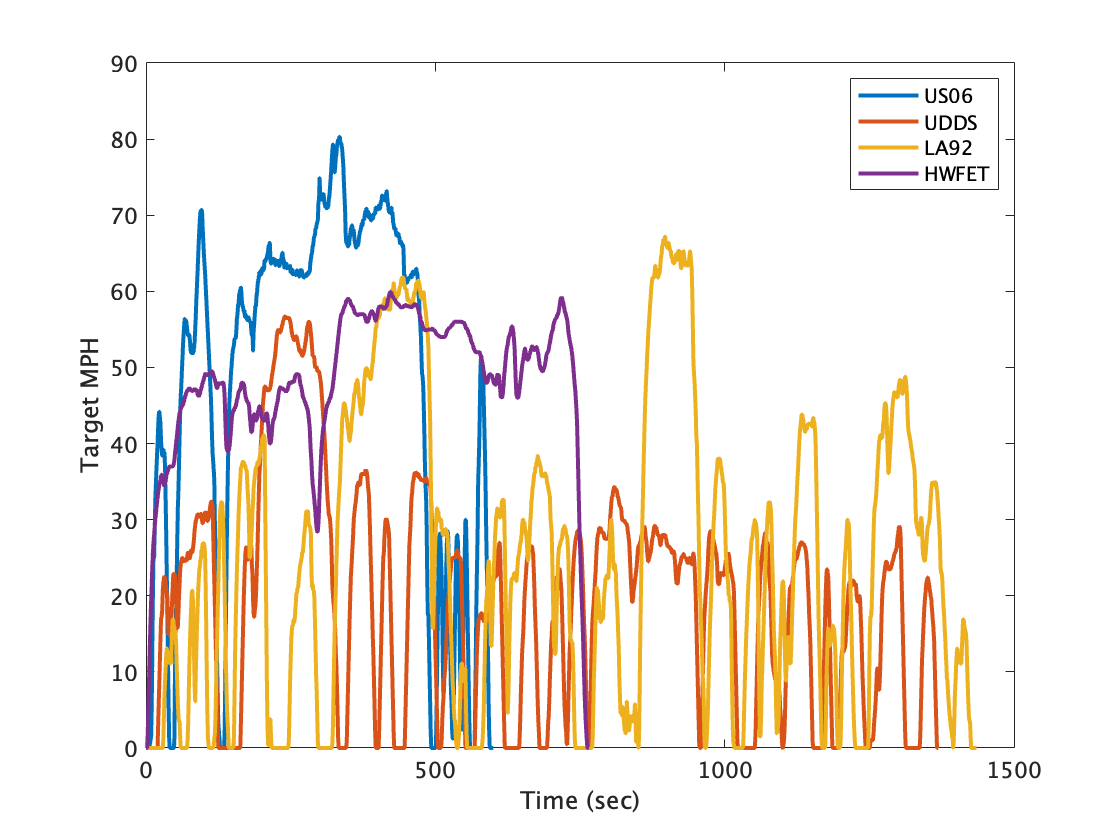

figure
cus06 = readtable('https://www.epa.gov/sites/production/files/2015-10/us06col.txt','NumHeaderLines',2);
cus06.Properties.VariableNames = ["Time","MPH"];
plot(cus06.Time, cus06.MPH, 'LineWidth', 2)
hold on

cudds = readtable('https://www.epa.gov/sites/production/files/2015-10/uddscol.txt','NumHeaderLines',2);
cudds.Properties.VariableNames = ["Time","MPH"];
plot(cudds.Time, cudds.MPH, 'LineWidth', 2)

cla92 = readtable('https://www.epa.gov/sites/production/files/2015-10/la92dds.txt','NumHeaderLines',2);
cla92.Properties.VariableNames = ["Time","MPH"];
plot(cla92.Time, cla92.MPH, 'LineWidth', 2)

chwfet = readtable('https://www.epa.gov/sites/production/files/2015-10/hwycol.txt','NumHeaderLines',2);
chwfet.Properties.VariableNames = ["Time","MPH"];
plot(chwfet.Time, chwfet.MPH, 'LineWidth', 2)
hold off
legend(["US06","UDDS","LA92","HWFET"])
xlabel("Time (sec)")
ylabel("Target MPH")

それぞれ持続時間も違います。最高速度は US06 が最も高く、 HWFET は加減速が少ない。UDDS, LA92 は頻繁な加減速があるという点で似ているが、LA02 の方が最高速度・平均速度は高い。UDDS は全般的に低速のように見受けられる。